# Gaussian Process Regression

clear
close all
clc

## Notation and Data Generation

x1,2: input of the training/test set N1*1 (only for observation sake, we will focus on feature instead of input)

phi1,2: features of the training/test set N1*M (design matrix)

w: weight M*1 

y1,2: ground truth of observation of the training/test set N1*1

beta: the percision of ther observation.

t1,2: noisy observations of the training/test set N1*1

Firstly, we need to generate the training data.

sig_observation=10;
beta=1/sig_observation^2; clear sig_observation
M=4;
% w=randn(M,1);
w = [-0.05,3,-0.6,-0.05]';
N1=100;

x1=(rand(N1,1)-0.5)*10;
x1=sort(x1);
phi1=poly_base(x1,M-1);
y1=phi1*w;
t1=y1+randn(N1,1)/sqrt(beta);

Now let's introduce some data from the test set:

N2=80;

x2=(rand(N2,1)-0.5)*20;
x2=sort(x2);
phi2=poly_base(x2,M-1);
y2=phi2*w;
t2=y2+randn(N2,1)/sqrt(beta);

Visualization

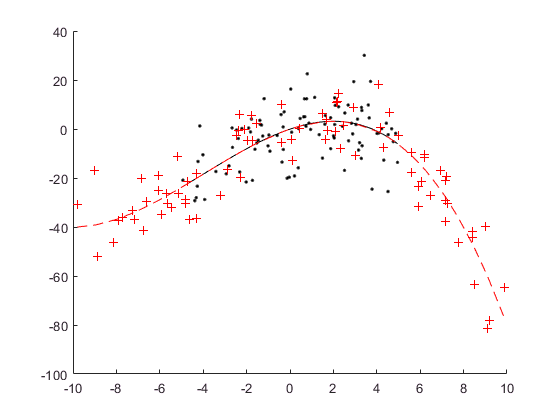

figure
hold on
hold on
plot(x1,y1,'k')
plot(x1,t1,'k.')
plot(x2,y2,'--r')
plot(x2,t2,'+r')

Then let's hide the test data observations in a file to avoid cheating:

save('test_observation.mat','y2','t2');
clear y2 t2

## From Linear regression to GP regression

Define a linear regression problem as:


$${\bf{y}}=
{\bf{\phi}}
{\bf{w}}$$


And the prior distribution of the weights are:


$$p({\bf{w}})=
\mathcal{N}
(0,
\alpha^{-1}
{\bf{I}})$$


In GP regression, we tend to discuss the distribution of **y** instead. Because phi is a matrix, it can be viewed as a linear transformation, so the distribution of **y** is also a Joint gaussian with mean and variance:


$${\bf{E}}({\bf{y}})=
{\bf{\phi}}*{\bf{E}}({\bf{w}})=
{\bf{0}}$$



$${\bf{Cov}}({\bf{y}})=
{\bf{E}}({\bf{yy}}^T) + 
{\bf{E}}({\bf{y}}){\bf{E}}({\bf{y}})^T=
{\bf{\phi}}
{\bf{E}}({\bf{ww}}^T)
{\bf{\phi}}^T=
{\bf{\phi\phi}}^T/\alpha$$


We define the last expression:


$${\bf{K}}={\bf{\phi\phi}}^T/\alpha$$


, where each element of K is:


$$K_{i,j}=\phi_{i,:}\ \phi_{j,:}^T\ /\alpha$$


, which is the inner product between samples.

Other than inner product, we can also use other kernel function k() to generate matrix **K**:


$$K_{i,j}=k(\phi_{i,:},\phi_{j,:})$$


## Find P(t)

In this section, we talk about the extended data set, denoted by variables without number. For Example:

phi=[phi1;phi2];
N=N1+N2;

Distribution for ground truth **y** is:


$$p({\bf{y}} )=\mathcal{N}(

{\bf{y}}|
{\bf{0}},
{\bf{K}})$$


, where **K** is calculated by kernel as below.

alpha=1;
K=mykernel(phi,phi,alpha); % inner product 

Distribution of noisy observation **t** given **y** is:


$$p({\bf{t}}|{\bf{y}})=\mathcal{N}

(
{\bf{y}},
\beta^{-1}{\bf{I}}_N
)$$


We know that Gausian distribution with a gaussian mean is still a Gaussian. So we have:


$$p({\bf{t}})
=\int_{-\infty}^{\infty}
p({\bf{t}}|{\bf{y}})
p({\bf{y}})
d{\bf{y}}
=\mathcal{N}(
{\bf{t}}|
{\bf{0}},
{\bf{C}})$$


Accoding to the properties of Gaussian distribution, the covariance matrix **C** of observation **t** is the sum of covariances:

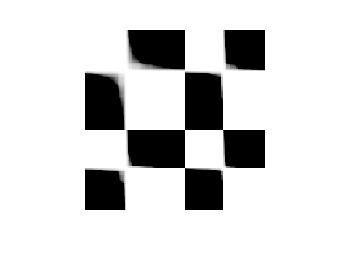

C=K+eye(N)/beta;
figure
imshow(C)

This does not give us any information in terms of regression, because this is only the probability of t given the features with the assumption of a kernel. The observation data in the training set is not used yet. 

## Prediction

Now we have the distribution of t for both trainning and test data, and it is a Gaussian. For our regression problem, **t1** is known, and **t2**, unknown. Because it is a MV-Gaussian, we can easily derive the condiational distribution of **t2** given **t1**.

The general conditional Gaussian distribution is found in the wiki page [wiki Conditional Gaussian distributions](https://en.wikipedia.org/wiki/Multivariate_normal_distribution#Conditional_distributions)

To use these equations, we need to have sections of **C**:

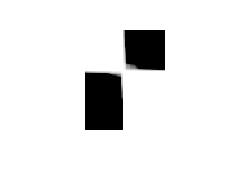

C11=C(1:N1,1:N1);
C22=C(N1+1:end,N1+1:end);
C12=C(1:N1,N1+1:end);
C21=C(N1+1:end,1:N1);

figure
imshow(C12)

And:

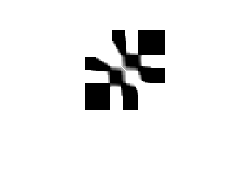

t2_Mu=C21*inv(C11)*(t1);
t2_C=C22-C21*inv(C11)*C12;
t2_sd=sqrt(diag(t2_C));
figure
imshow(t2_C)

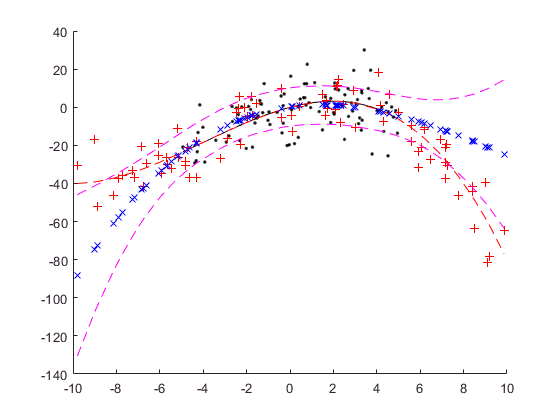

load test_observation.mat
figure
hold on
plot(x1,y1,'k')
plot(x1,t1,'k.')
plot(x2,y2,'--r')
plot(x2,t2,'+r')
plot(x2,t2_Mu,'bx')
plot(x2,t2_Mu+t2_sd,'m--')
plot(x2,t2_Mu-t2_sd,'m--')

% axis([-10,10,-80,40])

## Build in function

The document for the build in function is here: [fitrgp](https://www.mathworks.com/help/stats/fitrgp.html)

Using the default setting, Might not be very good

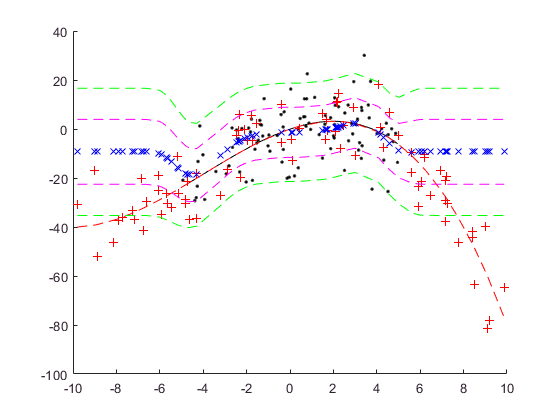

gprMdl = fitrgp(phi1,t1);
[t2_Mu,t2_sd,t2_95CI]= predict(gprMdl,phi2);
figure
hold on
plot(x1,y1,'k')
plot(x1,t1,'k.')
plot(x2,y2,'--r')
plot(x2,t2,'+r')
plot(x2,t2_Mu,'bx')
plot(x2,t2_95CI,'g--')
plot(x2,t2_Mu+t2_sd,'m--')
plot(x2,t2_Mu-t2_sd,'m--')

Other build in kernel

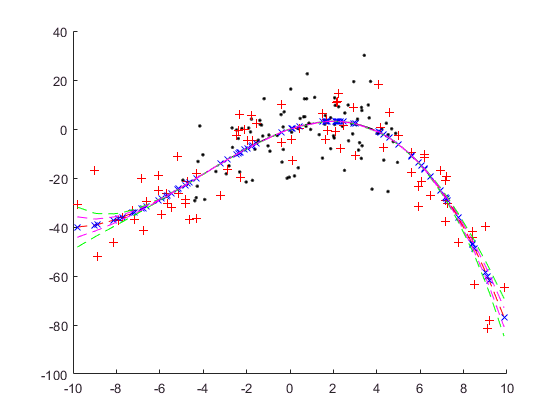

sigma0 = 0.2;
kparams0 = [3.5, 6.2];
gprMdl = fitrgp(phi1,y1,'KernelFunction','squaredexponential',...
     'KernelParameters',kparams0,'Sigma',sigma0);
[t2_Mu,t2_sd,t2_95CI]= predict(gprMdl,phi2);
figure
hold on
plot(x1,y1,'k')
plot(x1,t1,'k.')
plot(x2,y2,'--r')
plot(x2,t2,'+r')
plot(x2,t2_Mu,'bx')
plot(x2,t2_95CI,'g--')
plot(x2,t2_Mu+t2_sd,'m--')
plot(x2,t2_Mu-t2_sd,'m--')

Self defined kernel:

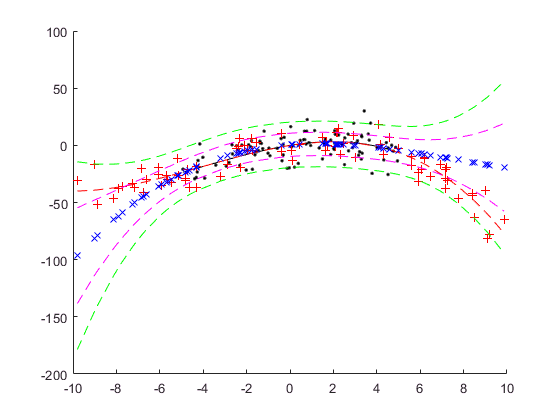

gprMdl = fitrgp(phi1,t1,'KernelFunction',@mykernel,'KernelParameters',alpha);
[t2_Mu,t2_sd,t2_95CI] = predict(gprMdl,phi2);
figure
hold on
plot(x1,y1,'k')
plot(x1,t1,'k.')
plot(x2,y2,'--r')
plot(x2,t2,'+r')
plot(x2,t2_Mu,'bx')
plot(x2,t2_95CI,'g--')
plot(x2,t2_Mu+t2_sd,'m--')
plot(x2,t2_Mu-t2_sd,'m--')

## Other readings

[1] Matlab's explantion of the Gaussian Process Regression: [Gaussian Process Regression Models](https://www.mathworks.com/help/stats/gaussian-process-regression-models.html)

[2] Bishop's MLPR book, Chapter 6: [Bishop: Pattern Recognition and Machine Learning](http://users.isr.ist.utl.pt/~wurmd/Livros/school/Bishop%20-%20Pattern%20Recognition%20And%20Machine%20Learning%20-%20Springer%20%202006.pdf)

[3] Hanna M. Wallach's lecture slides: [Introduction to Gaussian Process Regression](http://www.inference.org.uk/hmw26/papers/gp_intro.pdf)

[4] [Kriging](https://en.wikipedia.org/wiki/Kriging)

[5] EGO: Efficient Global Optimization

function phi = poly_base(x,max_order)
    phi=[];
    order_of_ploy=0:max_order;
    for o = order_of_ploy
        phi=[phi x.^o];
    end
end